# Speeding up variable frequency pulse generation (LLC Resonance Converter)

Copyright 2023-2024 The MathWorks, Inc.

LLC-Resonance Converters are a good example for electric power switching with variable frequencies.

Also in this case the simulation can often be sped up by slight modifications. The approach shown here can also be applied to other variable frequency based converters.

## How does a LLC-Resonance Converter work?

- The output voltage of the LLC-Resonance Converter is measured and compared with a reference value

- The difference between these two voltages is applied to a PI-controller that outputs a frequency value in the range of 1MHz

- The frequency value drives a VCO (voltage controlled osciallator) with variable frequency square wave output and a const 50% duty cycle

- The signal drives a halfbridge while considering short switch on delays on High and Low side to prevent short circuiting of the halfbridge.

- Such a high frequency resonance circuit is built up of a capacitance and inductors. One inductor is a transformer primary side. The resonance circuit has a low damping and, the amplitude of voltage and current are depending on the frequency.

- The secondary side is connected to full wave recitifier, whos output voltage is measured as described in the first line. 

The reference example here ("ee_converter_dcdc_llc.slx.slx") is a demo that is part of Simscape Electrical. This has been slightly modified to add a faster pulse generation capability as one variant.

Open the model

mdl = 'LLC_ResonanceConverter.slx';
open_system(mdl);

Save under a different file name to prevent reference model to be overwritten

save_system(mdl,'LLC_ResonanceConverter_modified.slx');
mdl = gcs;

A time measurement output has been added to model in the Stop-Fcn Callback

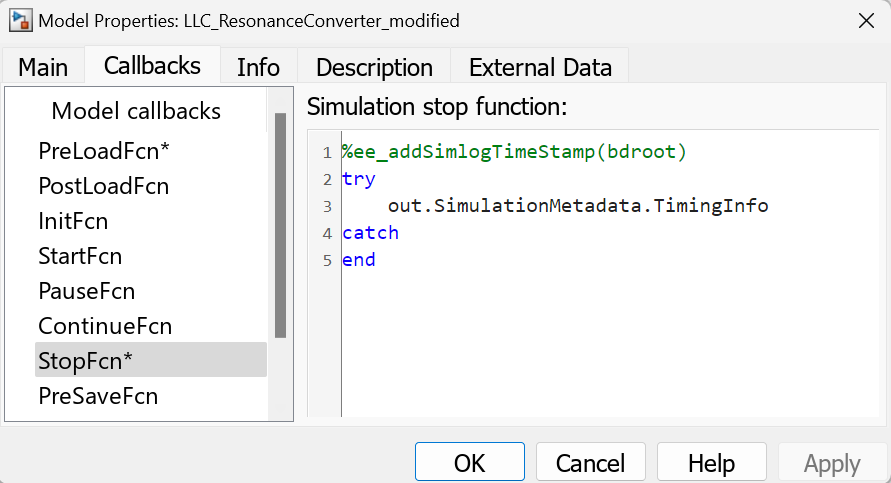

Additionally some logging points have been set.

Variable Step solver daessc is used.

### Reference Simulation

Measure current execution time

out1 = sim(bdroot);
out1.SimulationMetadata.TimingInfo

ans = struct with fields:
          WallClockTimestampStart: '2023-10-31 13:22:44'
           WallClockTimestampStop: '2023-10-31 13:23:40'
    InitializationElapsedWallTime: 6.7490
         ExecutionElapsedWallTime: 48.0896
       TerminationElapsedWallTime: 0.5849
             TotalElapsedWallTime: 55.4236
                     ProfilerData: 'Profiler is not enabled'


### Use Abstract Ideal Switch for faster simulation

switchType = 2;

out2 = sim(bdroot);
out2.SimulationMetadata.TimingInfo

ans = struct with fields:
          WallClockTimestampStart: '2023-10-31 13:40:24'
           WallClockTimestampStop: '2023-10-31 13:40:29'
    InitializationElapsedWallTime: 2.8084
         ExecutionElapsedWallTime: 1.6241
       TerminationElapsedWallTime: 0.0662
             TotalElapsedWallTime: 4.4987
                     ProfilerData: 'Profiler is not enabled'


#### Launch Solver Profiler to figure out bottlenecks

res = solverprofiler.launchSolverProfiler(mdl);

Set all check boxes and click RUN

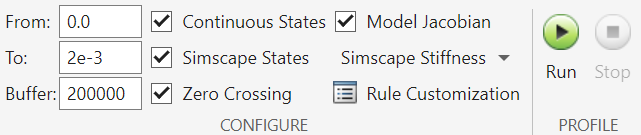

Enable View on Solver Exceptions, Jacobian Updates, Solver Resets and Zero-Crossings

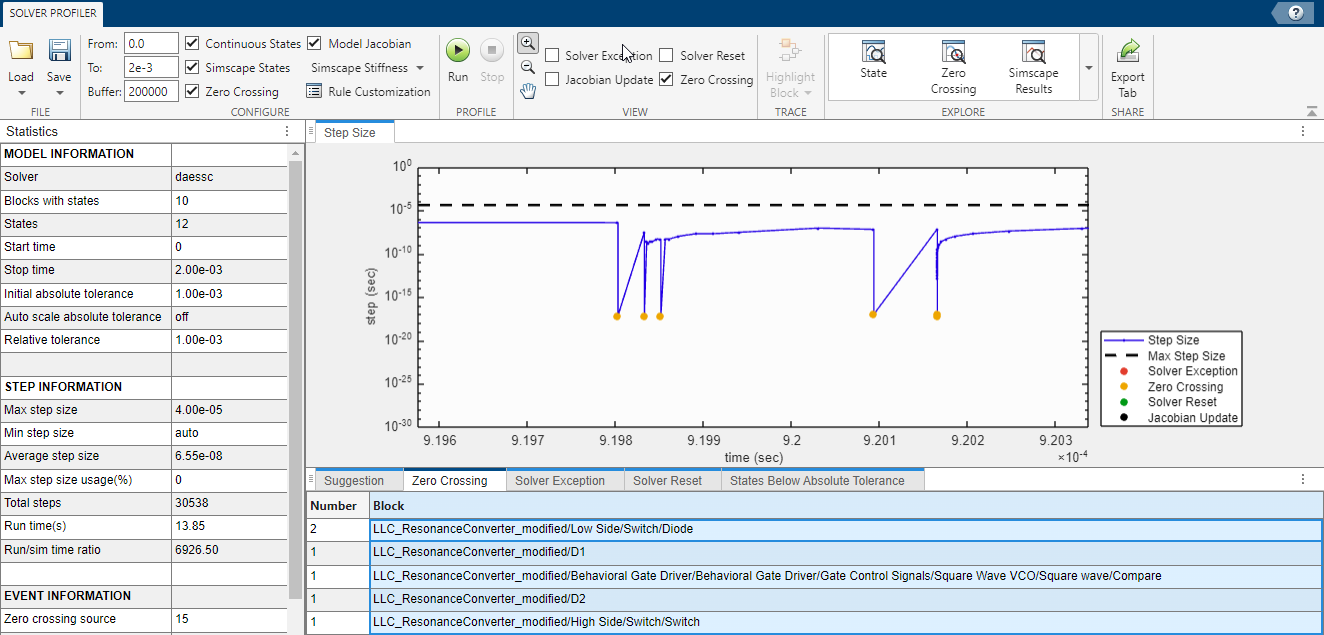

Zero Crossing are shown for 

- VCO comparator / Switch / Diode Halfbridge / Diode Rectifier

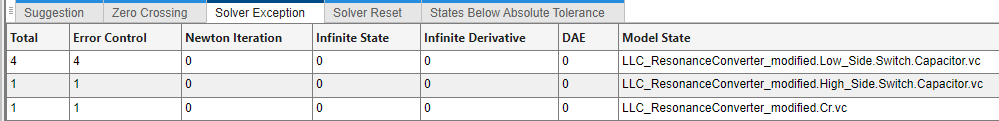

Solver Exceptions are also shown for 

- Capacitor

### Combine Switch and Halfbridge Diode to one Component, remove Switch Capacitors and Rate Limiter

switchType = 3;
set_param([mdl,'/Gate Driver/Behavioral',newline,'Gate Driver/Rate ',newline,'Limiter H'],'Commented','through');
set_param([mdl,'/Gate Driver/Behavioral',newline,'Gate Driver/Rate ',newline,'Limiter L'],'Commented','through');

out3 = sim(bdroot);
out3.SimulationMetadata.TimingInfo

ans = struct with fields:
          WallClockTimestampStart: '2023-10-31 13:50:30'
           WallClockTimestampStop: '2023-10-31 13:50:33'
    InitializationElapsedWallTime: 2.1923
         ExecutionElapsedWallTime: 0.9306
       TerminationElapsedWallTime: 0.0407
             TotalElapsedWallTime: 3.1636
                     ProfilerData: 'Profiler is not enabled'


### Use faster Simulink Variable Pulse Generator that does not use zero-crossing

Use faster Simulink Variable Pulse Generator that does not use zero-crossing

The original model uses switch-on delays at High and Low side which also causes zero-crossing during the simulation. This has been prevented with the faster switching concept, instead these delayed pulses are directly generated by additional Variable Pulse Generators.

Using this faster switching adds a small behavioral change to the model, because now the pulse switching times are precalculated for a period based on the frequency value that is applied at the beginning of the every pulse period. In the original model, the frequency even changed during the periode and caused slightly different switching times.

Mode = 1;

out4 = sim(bdroot);
out4.SimulationMetadata.TimingInfo

ans = struct with fields:
          WallClockTimestampStart: '2023-10-31 13:52:43'
           WallClockTimestampStop: '2023-10-31 13:52:46'
    InitializationElapsedWallTime: 2.2203
         ExecutionElapsedWallTime: 0.6634
       TerminationElapsedWallTime: 0.0471
             TotalElapsedWallTime: 2.9308
                     ProfilerData: 'Profiler is not enabled'


### Use Simulation Data Inspector instead of Scope to save time

set_param([mdl,'/Output'],'Commented','on');

out5 = sim(bdroot);
out5.SimulationMetadata.TimingInfo

ans = struct with fields:
          WallClockTimestampStart: '2023-10-31 13:53:14'
           WallClockTimestampStop: '2023-10-31 13:53:17'
    InitializationElapsedWallTime: 2.3519
         ExecutionElapsedWallTime: 0.6441
       TerminationElapsedWallTime: 0.0534
             TotalElapsedWallTime: 3.0494
                     ProfilerData: 'Profiler is not enabled'


### Compare simulation results with Simulation Data Inspector

Simulink.sdi.view;
Simulink.sdi.setSubPlotLayout(2,1);
Simulink.sdi.clear;


#### Reference Model with detailed MOSFET

Simulink.sdi.createRun('Reference','vars',out1);
lastRun = Simulink.sdi.Run.getLatest;
Vout = getSignalsByName(lastRun,'Vout');
plotOnSubPlot(Vout,1,1,true);
Vref = getSignalsByName(lastRun,'Reference');
plotOnSubPlot(Vref,2,1,true);

#### Model with Abstract Ideal Switch

Simulink.sdi.createRun('IdealSwitch','vars',out2);
lastRun = Simulink.sdi.Run.getLatest;
Vout = getSignalsByName(lastRun,'Vout');
plotOnSubPlot(Vout,1,1,true);
Vref = getSignalsByName(lastRun,'Reference');
plotOnSubPlot(Vref,2,1,true);

#### Model with Simplified Ideal Switch, removed Capacitors and removed Rate Limiter

Simulink.sdi.createRun('No C and Rate Limiter','vars',out3);
lastRun = Simulink.sdi.Run.getLatest;
Vout = getSignalsByName(lastRun,'Vout');
plotOnSubPlot(Vout,1,1,true);
Vref = getSignalsByName(lastRun,'Reference');
plotOnSubPlot(Vref,2,1,true);

#### Model with fast Simulink Variable Pulse Generator

Simulink.sdi.createRun('VariablePulseGenerator','vars',out4);
lastRun = Simulink.sdi.Run.getLatest;
Vout = getSignalsByName(lastRun,'Vout');
plotOnSubPlot(Vout,1,1,true);
Vref = getSignalsByName(lastRun,'Reference');
plotOnSubPlot(Vref,2,1,true);

####